% Create a time vector and initialize the trajectory parameters
t = linspace(0, 10, 100); % Time from 0 to 10 seconds
angular_velocity = 0.5;   % Angular velocity in rad/s
radius = 1;

% Define the constant speed in the X direction
speed_x = 3; % m/s

target_position = zeros(length(t), 3);
for i = 1:length(t)
    % Calculate the YZ plane position for the target in a circular trajectory

    target_position(i,:) = [speed_x*t(i); radius*cos(angular_velocity * t(i)); radius*sin(angular_velocity * t(i))];
end

% disp(target_position)

         0    1.0000         0
    0.3030    0.9987    0.0505
    0.6061    0.9949    0.1008
    0.9091    0.9885    0.1509
    1.2121    0.9797    0.2006
    1.5152    0.9683    0.2498
    1.8182    0.9544    0.2984
    2.1212    0.9382    0.3462
    2.4242    0.9195    0.3931
    2.7273    0.8985    0.4391
    3.0303    0.8752    0.4839
    3.3333    0.8496    0.5274
    3.6364    0.8219    0.5696
    3.9394    0.7921    0.6104
    4.2424    0.7603    0.6496
    4.5455    0.7265    0.6872
    4.8485    0.6909    0.7230
    5.1515    0.6535    0.7569
    5.4545    0.6145    0.7889
    5.7576    0.5739    0.8190
    6.0606    0.5318    0.8469
    6.3636    0.4883    0.8727
    6.6667    0.4437    0.8962
    6.9697    0.3979    0.9174
    7.2727    0.3510    0.9364
    7.5758    0.3033    0.9529
    7.8788    0.2548    0.9670
    8.1818    0.2057    0.9786
    8.4848    0.1560    0.9878
    8.7879    0.1060    0.9944
    9.0909    0.0556    0.9985
    9.3939    0.0051    1.0000
    9.69


% Create a 3D trajectory plot
% figure;  % Create a new figure
% plot3(target_position(:,1),target_position(:,2), target_position(:,3), 'b', 'LineWidth', 2);  % Plot the trajectory in blue with a thick line
% grid on;  % Show a grid
% xlabel('X-axis');
% ylabel('Y-axis');
% zlabel('Z-axis');
% title('3D Trajectory Plot'); 

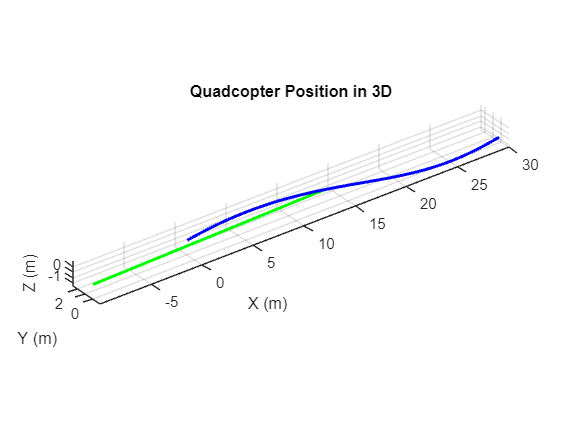

% Define initial state
initial_position = [-10; 0; 0];  % [x, y, z] in meters
initial_velocity = [0; 0; 0];  % [vx, vy, vz] in m/s
initial_roll = 0;               % Initial roll angle in radians
initial_pitch = 0;              % Initial pitch angle in radians
initial_yaw = 0;                % Initial yaw angle in radians
initial_state = [initial_position; initial_velocity; initial_roll; initial_pitch; initial_yaw];
mass = 2;           % Mass of UAV
focal_length = 800; % Focal length of the camera
image_width = 640; % Width of the image plane
image_height = 480; % Height of the image plane
fov_horizontal = deg2rad(60); % 60 degrees horizontal FOV
fov_vertical = deg2rad(40);   % 40 degrees vertical FOV

% Initialize time parameters
total_time = 10;  % Total simulation time in seconds
dt = 0.1;         % Time step in seconds
num_steps = total_time / dt;

% Initialize arrays to store state at each time step
states = zeros(9, num_steps);

% Initialize a variable to store the image coordinates of the target points
image_coordinates = zeros(length(t), 2);

% Loop for simulation
current_state = initial_state;
for step = 1:num_steps
    % Define control inputs (e.g., changing roll, pitch, yaw angles and thrust)
    roll = -0.01;       %0.1 * sin(0.5 * step * dt);   % Example: Roll angle changes over time
    pitch = 0.1;    %0.1 * cos(0.5 * step * dt);  % Example: Pitch angle changes over time
    yaw = 0;        %0.05 * sin(0.3 * step * dt);   % Example: Yaw angle changes over time
    thrust = 9.81;                        % Example: Constant thrust
    action = [roll, pitch, yaw, thrust];
    % Call the quadcopter_dynamics function to update the state
    new_state = quadcopter_dynamics(current_state, action, mass, dt);

    % Store the new state in the states array
    states(:, step) = new_state;

    % Update the current state for the next iteration
    current_state = new_state;

    camera_position = current_state(1:3);
    camera_orientation = current_state(7:9);

    % Translate the target points to the camera coordinate system
    relative_positions = target_position(step,:) - camera_position';
    
    R = rotationMatrix(camera_orientation);
    rotated_positions = (R * relative_positions')';

    % Check if the point is within the camera's field of view
    if isWithinFOV(rotated_positions, fov_horizontal, fov_vertical)
        % Calculate the projection using the pinhole camera model
        image_x = (focal_length / rotated_positions(1)) * rotated_positions(2);
        image_y = (focal_length / rotated_positions(1)) * rotated_positions(3);

        image_coordinates(step, :) = [image_x image_y];
    else
        % Point is outside the field of view, set the image coordinates to NaN
        image_coordinates(step, :) = [NaN NaN];
        % disp('Out of FOV')
    end

end


% Plot the 3D position of the quadcopter over time
position = states(1:3, :);
figure;
plot3(position(1, :), position(2, :), position(3, :),'g', 'LineWidth', 2);
hold on; % Add the second trajectory to the same plot
plot3(target_position(:, 1), target_position(:,2), target_position(:,3),'b', 'LineWidth', 2);
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');
title('Quadcopter Position in 3D');
grid on;
axis equal;

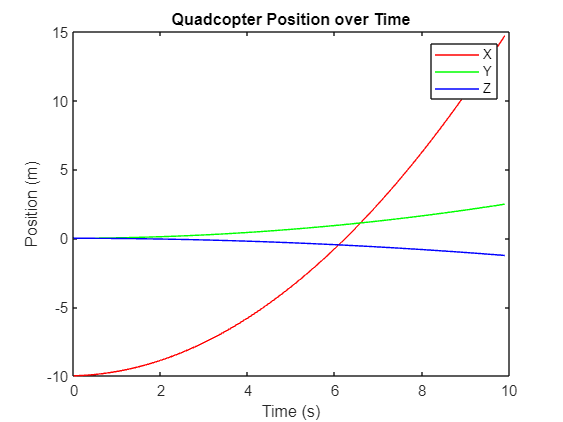


% Plot the position over time
time = 0:dt:(total_time - dt);
position = states(1:3, :);
figure;
plot(time, position(1, :), 'r', time, position(2, :), 'g', time, position(3, :), 'b');
xlabel('Time (s)');
ylabel('Position (m)');
legend('X', 'Y', 'Z');
title('Quadcopter Position over Time');

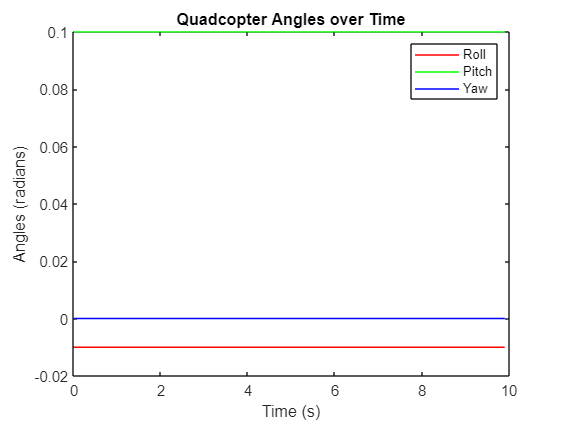


% Plot the roll, pitch, and yaw angles over time
time = 0:dt:(total_time - dt);
angles = states(7:9, :);
figure;
plot(time, angles(1, :), 'r', time, angles(2, :), 'g', time, angles(3, :), 'b');
xlabel('Time (s)');
ylabel('Angles (radians)');
legend('Roll', 'Pitch', 'Yaw');
title('Quadcopter Angles over Time');

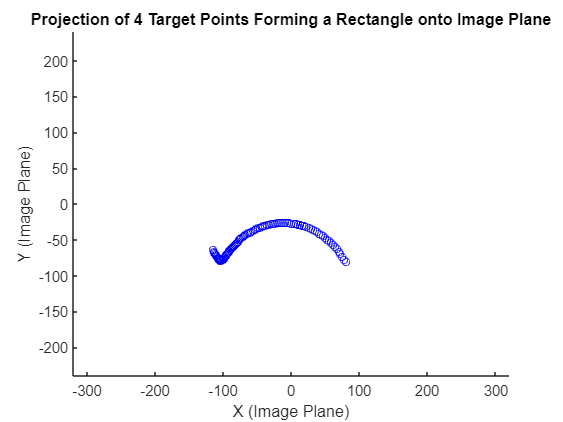


% Plot the target points' trajectories on the image plane using a for loop
figure;
hold on;
axis([-image_width/2, image_width/2, -image_height/2, image_height/2]);
xlabel('X (Image Plane)');
ylabel('Y (Image Plane)');
title('Projection of 4 Target Points Forming a Rectangle onto Image Plane');

% Define colors for each point
point_colors = ['bo', 'ro', 'go', 'mo'];

for i = 1:length(t)
    plot(image_coordinates(i, 1), image_coordinates(i, 2), 'bo', 'MarkerSize', 5);
    pause(0.01); % Add a pause for visualization (adjust as needed)
end

function new_state = quadcopter_dynamics(current_state, action, mass, dt)
    % Define constants
    g = 9.81;  % gravitational acceleration (m/s^2)

    % Unpack current state
    position = current_state(1:3);
    velocity = current_state(4:6);
    current_roll = current_state(7);
    current_pitch = current_state(8);
    current_yaw = current_state(9);

    roll = action(1);
    pitch = action(2);
    yaw = action(3);

    % Compute acceleration due to thrust and gravity
    R = rotationMatrixEulerZYX(roll, pitch, yaw);
    thrust_force = [0; 0; thrust];
    gravity_force = [0; 0; -g];
    total_force = R * thrust_force + gravity_force;
    acceleration = total_force / mass;  % m is the mass of the quadcopter

    % Update velocity and position
    new_velocity = velocity + acceleration * dt;
    new_position = position + new_velocity * dt;

    % Update roll, pitch, and yaw angles
    new_roll = roll;
    new_pitch = pitch;
    new_yaw = yaw;

    % Update the state vector
    new_state = [new_position; new_velocity; new_roll; new_pitch; new_yaw];
end

function R = rotationMatrixEulerZYX(roll, pitch, yaw)
% Euler ZYX angles convention
    Rx = [ 1,           0,          0;
           0,           cos(roll),  -sin(roll);
           0,           sin(roll),   cos(roll) ];
    Ry = [ cos(pitch),  0,          sin(pitch);
           0,           1,          0;
          -sin(pitch),  0,          cos(pitch) ];
    Rz = [cos(yaw),    -sin(yaw),   0;
          sin(yaw),     cos(yaw),   0;
          0,            0,          1 ];
    if nargout == 3
        % Return rotation matrix per axes
        return;
    end
    % Return rotation matrix from body frame to inertial frame
    R = Rz*Ry*Rx;
end

function R = rotationMatrix(angles)
    roll = angles(1);
    pitch = angles(2);
    yaw = angles(3);
    
    R_x = [1, 0, 0;
           0, cos(roll), -sin(roll);
           0, sin(roll), cos(roll)];
    
    R_y = [cos(pitch), 0, sin(pitch);
           0, 1, 0;
           -sin(pitch), 0, cos(pitch)];
    
    R_z = [cos(yaw), -sin(yaw), 0;
           sin(yaw), cos(yaw), 0;
           0, 0, 1];
    
    R = R_z * R_y * R_x;
end

% Function to check if a point is within the camera's FOV
function withinFOV = isWithinFOV(point, fov_horizontal, fov_vertical)
    if abs(atan2(point(2), point(1))) <= fov_horizontal/2 && abs(atan2(point(3), point(1))) <= fov_vertical/2
        withinFOV = true;
    else
        withinFOV = false;
    end
end